load('case_study.mat');
mn = mean(LOD)

mn = 1.7759e+04

lod = LOD - mn;
[imf, residual, info] = emd(LOD,'Interpolation','pchip');

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.022354   |  SiftMaxRelativeTolerance
      2      |        2     |     0.084255   |  SiftMaxRelativeTolerance
      3      |        3     |      0.14623   |  SiftMaxRelativeTolerance
      4      |        2     |     0.082125   |  SiftMaxRelativeTolerance
      5      |        2     |     0.050674   |  SiftMaxRelativeTolerance
      6      |        3     |     0.044187   |  SiftMaxRelativeTolerance
      7      |        3     |     0.030779   |  SiftMaxRelativeTolerance
      8      |        2     |     0.053471   |  SiftMaxRelativeTolerance
      9      |        2     |     0.016807   |  SiftMaxRelativeTolerance
The decomposition stopped because the number of extrema of the residual signal is less than 'MaxNumExtrema'.


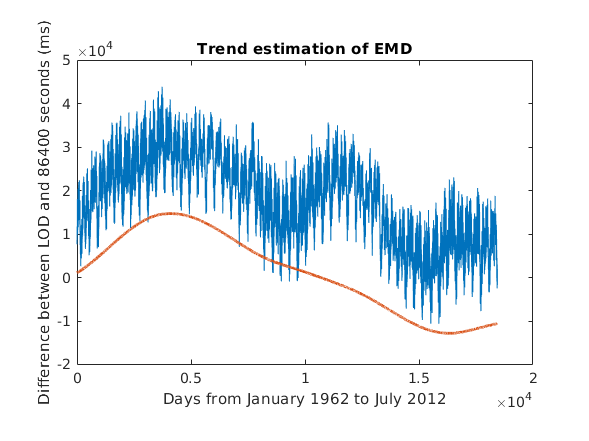

figure
plot(LOD)
hold on
plot(imf(:,9),'LineWidth',2)
title('Trend estimation of EMD')
xlabel('Days from January 1962 to July 2012')
ylabel('Difference between LOD and 86400 seconds (ms)')
pbaspect([12 8 1])